format long
N = 400; %Number of independent Bernoulli Trials
x = 0:400; % Number of Successes
p = 0.01;

lambda = N*p; %Probability of Success
y = binopdf(x, N, p); %Binomial PDF in-built funrion with parameter x and p
z = poisspdf(x, lambda); %Poisson PDF

# Plotting The Probability Against The Bernoulli Trials

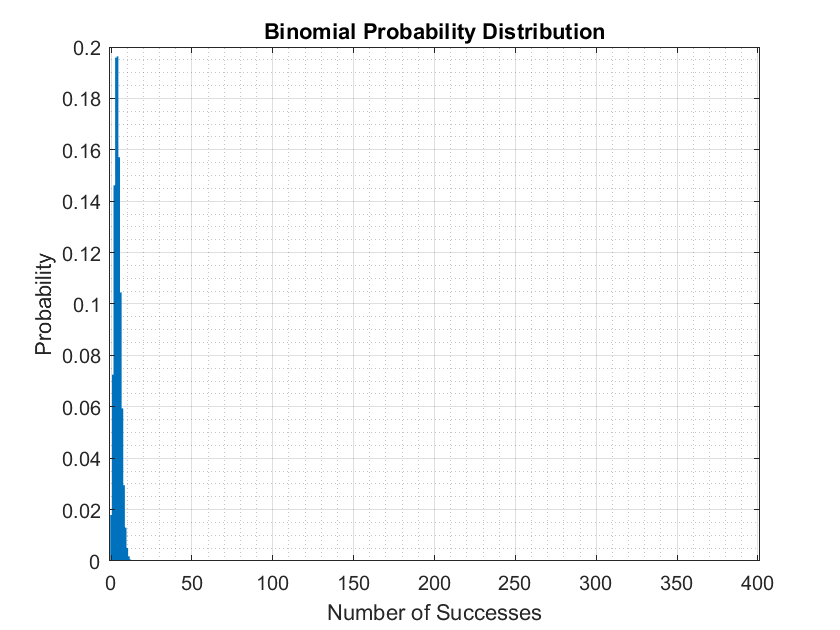

bar(x, y, 1) % Histogram of outputs
grid on; grid minor;
xlabel('Number of Successes')
ylabel('Probability')
title("Binomial Probability Distribution")

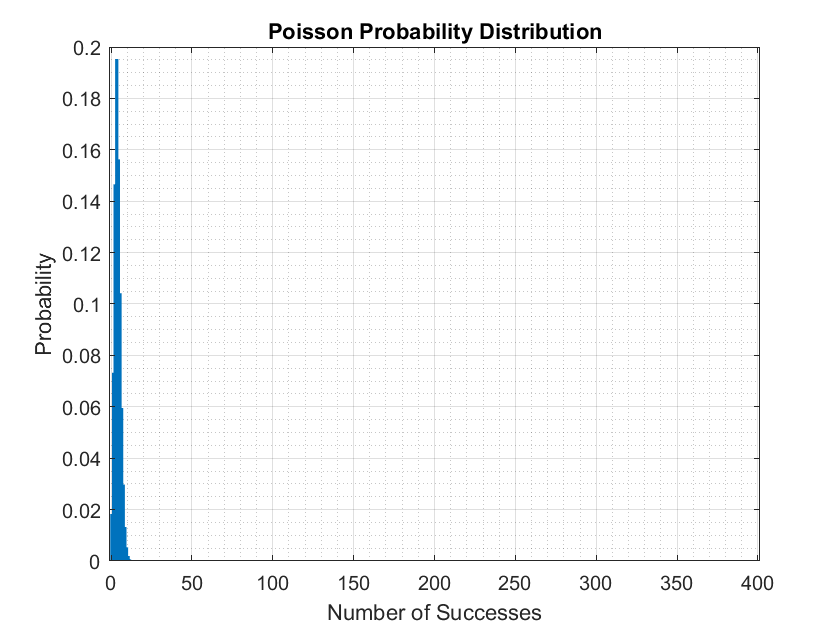



bar(x,z,1)
grid on; grid minor;
title("Poisson Probability Distribution")
xlabel('Number of Successes')
ylabel('Probability')

# Normality Test

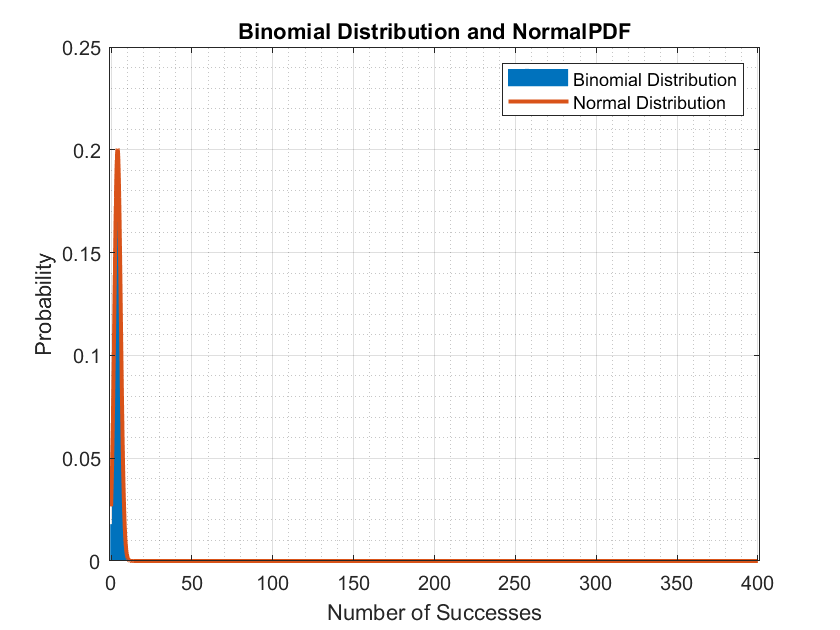

mu = N*p;
sigma = sqrt(mu*(1-p));
x2 = 0:0.1:N;
y2 = normpdf(x2, mu, sigma);
bar(x,y,1)
hold on
plot(x2, y2, 'LineWidth', 2)
xlabel('Number of Successes')
ylabel('Probability')
title('Binomial Distribution and NormalPDF')
grid on; grid minor;
legend('Binomial Distribution','Normal Distribution')
hold off;

# Negative Binomial Probability Distribution

## `A sample question on negative binomial probability `

`A person conducting telephone surveys must get 3 more completed surveys before their job is finished. `

`On each randomly dialed number, there is a 9% chance of reaching an adult who will complete the survey. `

`What is the probability that the 3rd completed survey occurs on the 10th call?`

`Solution`


$$$$ r = 3, p = 0.09, P(X=10) $$$$


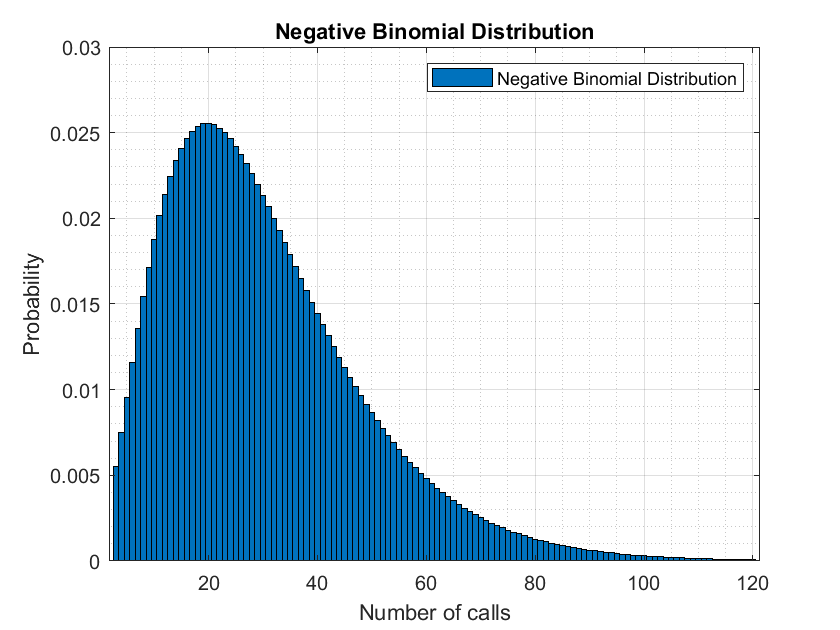


% Set the number of successes required
r = 3;

% Set the probability of success in each Bernoulli trial
p = 0.09;
 
k = 3:120;
y2 = nbinpdf(k, r, p);
bar(k,y2,1);
grid on; grid minor;
legend('Negative Binomial Distribution')
xlabel('Number of calls')
ylabel('Probability')
title('Negative Binomial Distribution')

## `Sample question on negative binomial probability `

`Jim is writing an exam with multiple-choice questions, and his probability of attempting the question with the right answer is 60%. `

`What is the probability that Jim gives the 3rd correct answer for the fifth attempted question?`

`Solution`


$$$$ r = 3, p = 0.6, P(X=5) $$$$


% Set the number of successes required
r1 = 3;

% Set the probability of success in each Bernoulli trial
p1 = 0.6;
 
k1 = 5:120;

k1 =      5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54


y3 = nbinpdf(k1, r1, p1);

y3 =     0.0464    0.0248    0.0127    0.0064    0.0031    0.0015    0.0007    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


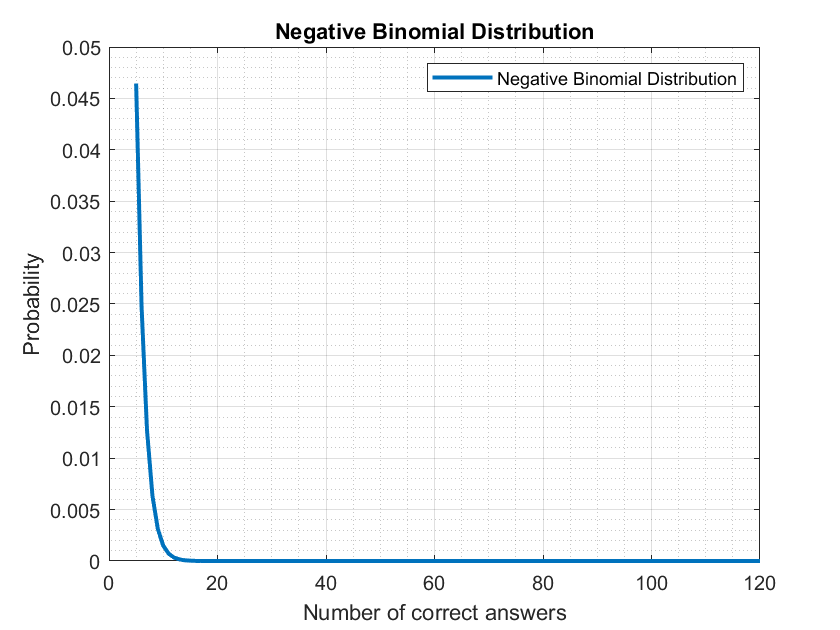

bar(k1,y3,1);
% plot(k1, y3, "LineWidth", 2)
grid on; grid minor;
legend('Negative Binomial Distribution')
xlabel('Number of correct answers')
ylabel('Probability')
title('Negative Binomial Distribution')

# Probability Density Function(PDF)


$$\[
f(x) =
\begin{cases}
\frac{1}{4}x, & \text{if } 0\leq  x\leq 2 \\
\frac{x}{4}, &\text{if } 2\leq  x\leq 4 \\
0, & \text{otherwise}
\end{cases}
\]
$$


where $f(x)$ is a probability density function

syms x
f(x) = piecewise((0 <= x) & (x <= 2), (1/4)*x, (2 <= x) & (x <= 4), 1-(1/4)*x,0)

$$f(x) = \left\{ \begin{array}{cl} \frac{x}{4} & \text{ if }x\in \left[0,2\right]\\ 1-\frac{x}{4} & \text{ if }x\in \left[2,4\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

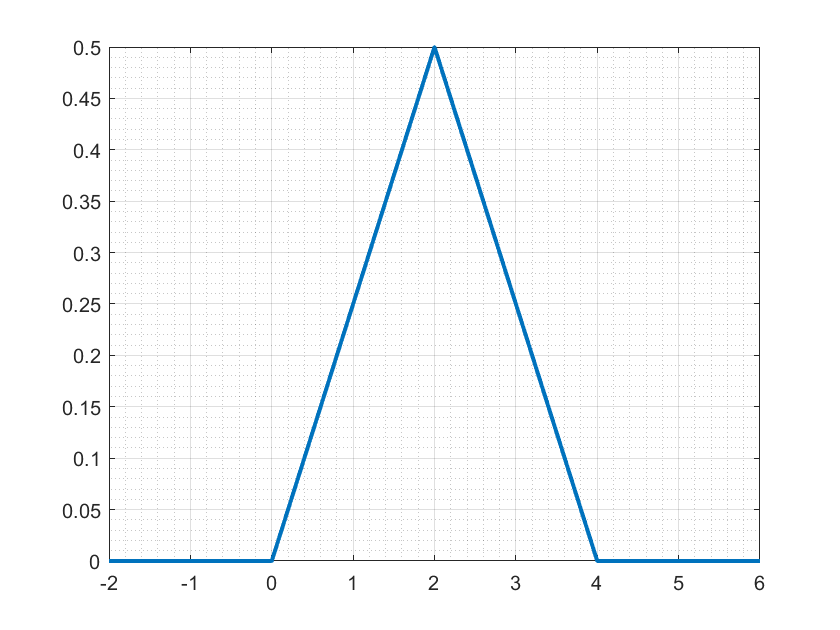

fplot(f,[-2 6], "LineWidth",2);
grid minor; grid on;

## Distributions

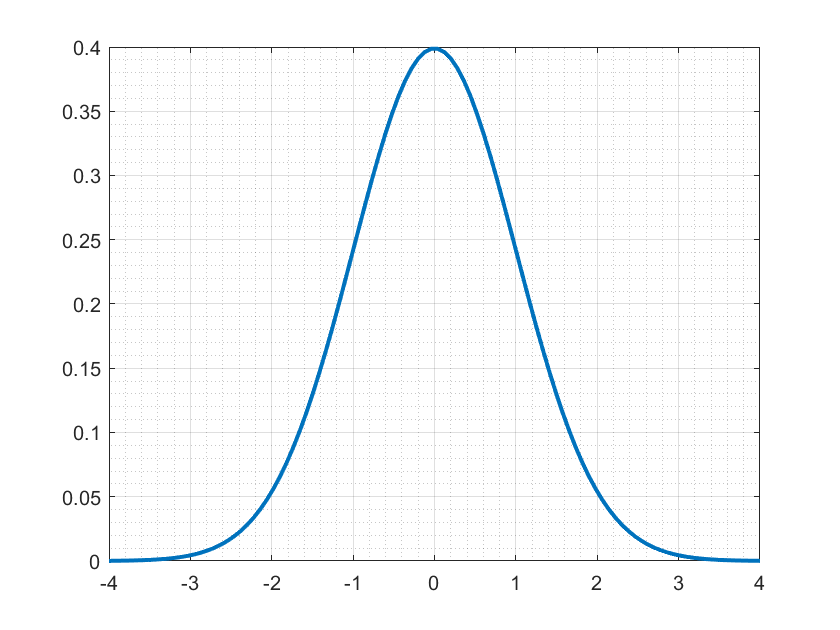

pd = makedist('Normal');
x = linspace(-4, 4, 100);
pdf_normal = pdf(pd,x);
plot(x,pdf_normal,'LineWidth',2);
grid on; grid minor;